# Opgave 1: Sandsynlighedsregning

**Et system er udviklet til at registrere om RFID tags er defekte. En undersøgelse viser, at givet et RFID tag ikke er defekt, er sandsynligheden for, at systemet registrerer, at det ikke er defekt, lig med 0,4. Og givet et RFID tag er defekt, er sandsynligheden for, at systemet registrerer, at det er defekt, lig med 0,999.**

**Vi ved at 1 ud af 100 RFID tags er defekte.**

Vi kender til disse værdier


$$\begin{array}{l}
R=\textrm{RFID}\;\textrm{IKKE}\;\textrm{DEFEKT}\\
\textrm{Not}\_R=\textrm{RFID}\;\textrm{DEFEKT}\\
\;S=\textrm{System}\;\textrm{registrere}\;\textrm{ingen}\;\textrm{fejl}\\
\textrm{Not}\_S=\textrm{System}\;\textrm{registrere}\;\textrm{fejl}
\end{array}$$



$$\begin{array}{l}
\left.\Pr \left(S\right|R\right)=0\ldotp 4\\
\left.\Pr \left(\bar{\;S} \;\right|\bar{\;R} \right)=0\ldotp 999\\
\Pr \left(\bar{\;R} \right)=\frac{1}{100}=0\ldotp 01
\end{array}$$


**a) Hvad er sandsynligheden for at et RFID tag ikke er defekt?**


$$\Pr \left(R\right)=1-\Pr \left(\bar{\;R} \;\right)=0\ldotp 99$$


*0.99*

**b) Hvad er den totale sandsynlighed for at systemet registrerer et RFID tag som defekt?**


$$\begin{array}{l}
\left.\Pr \left(\bar{\;S} \left|R\right.\right)=1-\Pr \left(S\right|R\right)=0\ldotp 6\\
\Pr \left(S\right)=\Pr \left(S\right|R\right)\cdot \Pr \left(R\right)+\Pr \left(S\left|\bar{\;R} \right)\cdot \Pr \left(\bar{\;R} \right)=0\ldotp 396\\
\Pr \left(\bar{\;S} \right)=1-\Pr \left(S\right)=0\ldotp 604
\end{array}$$


*Den totale sandsynlighed for at registrere defekt tag er 60.4%*

**c) Hvad er sandsynligheden, givet at et RFID tag registreres som defekt, at det også er defekt?**

Bayes regel:


$$\begin{array}{l}
\Pr \left(R\left|\bar{\;S} \right.\right)=\frac{\Pr \left(\bar{\;S} \left|R\right.\right)\cdot \Pr \left(R\right)}{\Pr \left(\bar{\;S} \right)}=0\ldotp 983\\
\Pr \left(\bar{\;R} \left|\bar{\;S} \right.\right)=1-\Pr \left(R\left|\bar{\;S} \right.\right)=0\ldotp 017
\end{array}$$


*givet at et RFID tag registreres som defekt, er sandsynligheden for at det også er defekt 1.7%*

**d) Hvad er sandsynligheden, givet at et RFID tag registreres som defekt, at det ikke er defekt?**


$$\Pr \left(R\left|\;\bar{\;S} \right.\right)=0\ldotp 983$$


*givet at et RFID tag registreres som defekt, er sandsynligheden for at det IKKE er defekt 98.3%*

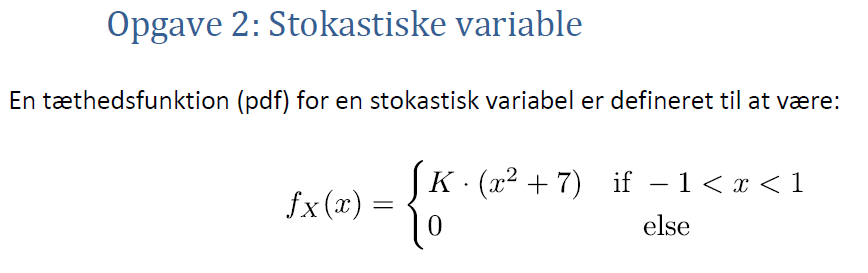

**a) Vis at K=3/44 , for at fX(x) er en gyldig tæthedsfunktion (pdf). Skitsér fX(x)**

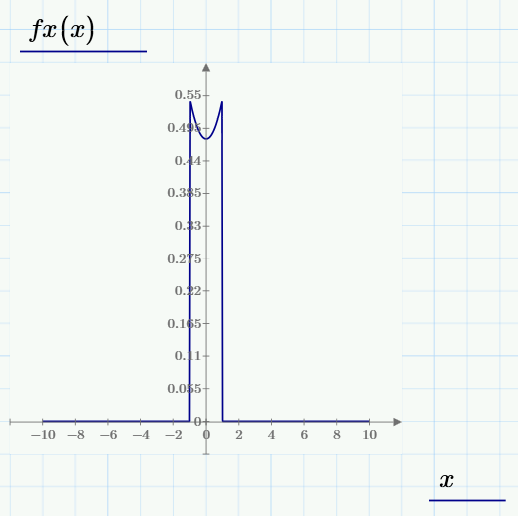

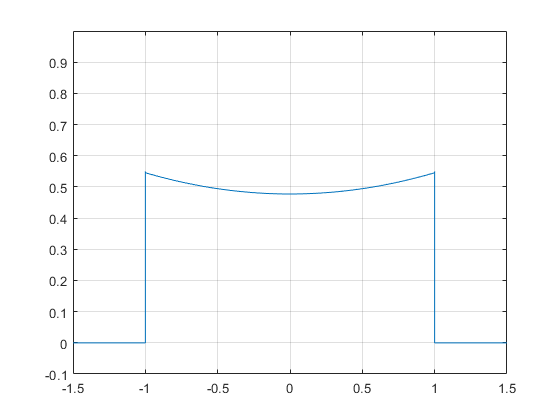

syms x;
fx=(3/44)*((x^2)+7);
figure;
fplot(fx,[-1 1])
line([-1.5,-1],[0,0])
line([-1,-1],[0,0.55])
line([1.5,1],[0,0])
line([1,1],[0,0.55])
grid 
axis([-1.5,1.5,-0.1,1])

**b) Opstil udtrykket for og find middelværdien (forventningsværdien) af X**

**middelværdi:**


$$E\left\lbrack X\right\rbrack =\int_{-\infty }^{\infty \;} x\cdot f_X \left(x\right)$$


**Middelværdi er 0**

**varians:**


$$E\left\lbrack X^2 \right\rbrack =\int_{-\infty }^{\infty \;} x^2 \cdot f_X \left(x\right)$$



$$\textrm{Var}\left(x\right)=\sigma {\;}_X^2 =$$

$$E\left\lbrack X^2 \right\rbrack -E{\left\lbrack X\right\rbrack }^2 =0\ldotp 345-0^2 =0\ldotp 345$$


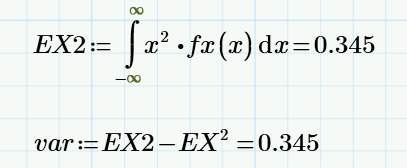

***variansen er 0.345***

**c) Opstil udtrykket for og find standard afvigelsen af X.**


$$\textrm{SD}\left(X\right)=\sigma {\;}_X =\sqrt{\sigma {\;}_X^2 }$$


*standard afvigelsen er 0.588*

**d) Opstil udtrykket for og find fordelingsfunktionen (cdf’en) for X.**

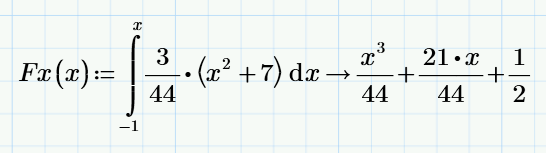


$$F_x(x) = \left\{ 
\matrix{
0 & , for & x < -1 \cr
\frac{x^3}{44}+\frac{21\cdot x}{44}+\frac{1}{2} & , for & -1 \leq x < 1 \cr
1 & , for &  x > 1 \cr

}$$


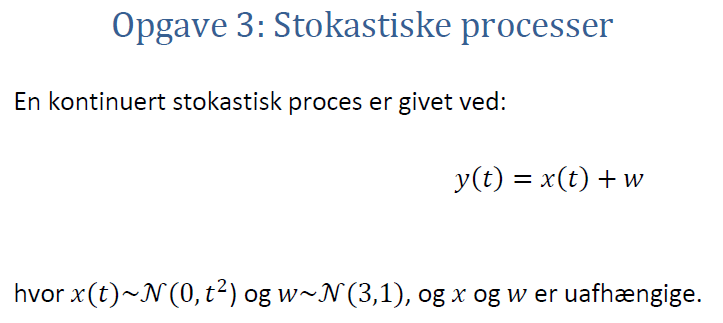

**a) Tegn 3 realisationer af y, der er samplet med en periodetid på 1s, i intervallet**

$0s\le t\le 10s$**. Skriv hvorledes realisationerne er fremkommet ved brug af en Gauss generator, f.eks. randn() i Matlab.**

yt =     0.8427   -0.7738    0.8802   -0.4352   -7.2934   -5.8001   -1.0766    6.6207   -0.9916    3.2030   -8.1371


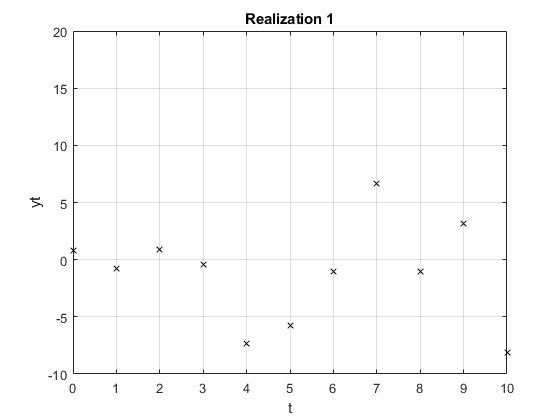

yt =     3.6768    2.7256    6.0220    8.8821    2.1900    9.6411    9.3987   -6.2285    3.4099    6.0268    8.9067


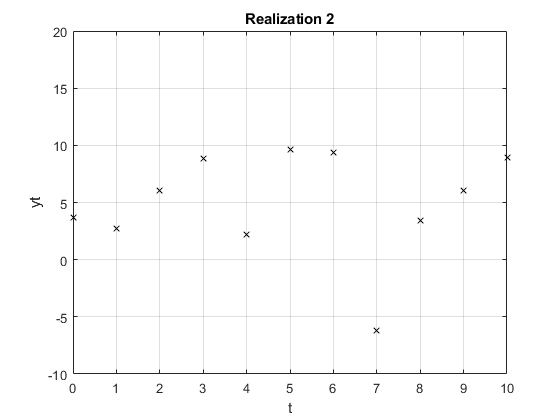

yt =     2.0407    2.7191    1.4156    3.1784   -6.9709   -3.8010    9.2525   -2.5845    4.6612   15.6139   -6.8484


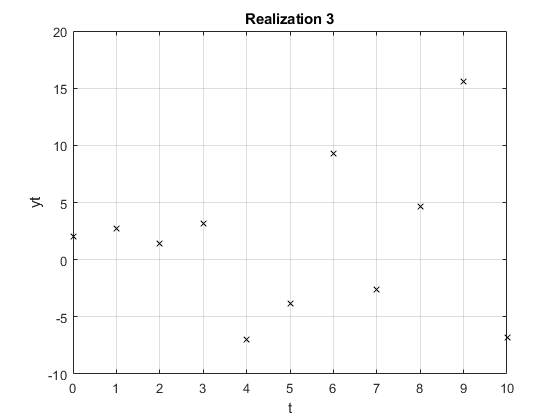

%Three realizations 11 samples
% der samples hvert sekund og vi kigger på intervallet 0 til 10. derfor
% skal der laves 11 samples.

t=0:1:10;
xmu = 0;
wsigma=1;
wmu=3;
T=11;
for i=1:3 %1:3 because we need 3 realizations
x=(randn(1,11).*t);
w=(randn+3);
    yt=x+w
    figure;
    n=1:10;%10 samples between 10-1
    plot(t,yt,'kx')
    grid
    axis([0,10,-10,20])%set values(length) for x and y axis
    title(['Realization ',num2str(i)])%axis title
    xlabel('t');
    ylabel('yt');
end

**b) Opskriv et udtryk og udregn ensemble middelværdien for processen y(t).**

middelværdi for kontinueret uniform er $\mu \;$ 

så formlen ser således ud


$$E\left\lbrack \textrm{yt}\right\rbrack =E\left\lbrack x\right\rbrack +E\left\lbrack W\right\rbrack =0+3=3$$


ensemble_mean=0+3

ensemble_mean = 3

ensemble mean: 3

**c) Opskriv et udtryk og udregn ensemble variansen for processen y(t).**

Variansen for en kontinueret uniformfordeling er $\sigma {\;}^2$


$$\textrm{var}\left(t\right)=\textrm{var}\left\lbrack x\right\rbrack +\textrm{var}\left\lbrack w\right\rbrack =t^2 +1=t^2 +1$$


ensemble var: $t^2 +1$

**d) Opskriv udtryk for den tidslige middelværdi og varians for én realisation af processen y(t).**


$$\begin{array}{l}
\mathrm{temporalMiddel}=\hat{\;\mu {\;}_{X_i } } =\underset{T\to \infty }{\mathrm{lim}} \cdot \frac{1}{T}\cdot \sum_{i=0}^n y_i \left(t\right)\\
\mathrm{temporalVarians}=\underset{T\to \infty }{\hat{\;\sigma {\;}_{X_i }^2 } =\mathrm{lim}} \cdot \frac{1}{T}\cdot \sum_{i=0}^n \left(y_i {\left(t\right)}^2 -\hat{\;\mu {\;}_{X_i }^2 } \right)
\end{array}$$


Grunden til at der bruges sum og ikke integral er fordi vi kun tager hele tal, altså sekunder.

temporal_mean=(1/T)*sum(yt)

temporal_mean = 1.6979

temporal_mean2=mean(yt)

temporal_mean2 = 1.6979

meanX=0;
temporal_var=vpa((1/T)*sum((x.^2)-meanX^2)) %Not sure this is right

$$temporal\_var = 41.908687237081466037125210277736$$

temporal_var2=var(yt)

temporal_var2 = 45.9703

**e) Er processen y(t) stationær i den brede forstand (WSS)? Er den ergodisk? Begrund dine svar.**

**Den er ikke WSS eller ergodisk.**

**Tid er taget i betragtning derfor er den ikke WSS**

** Den er ikke ergodisk fordi dens temporale og ensemble varians, samt middelværdi ikke er ens.**

# **Opgave 4: Statistik**

**Til kvalitetssikring af en produktion er udviklet et automatisk overvågningssystem, der skal registrere om en komponent er monteret korrekt. Overvågningssystemet skal i 95% af tilfældene registrere komponenterne korrekt, dvs. fejl-monterede komponenter registreres som fejl og korrekt-monterede komponenter registreres som korrekte.**

**For at undersøge om systemet overholder dette krav laves en række måleserier på et produkt A, hvor der testes om overvågningssystemets succesrate er præcis 95%. Testen består af i alt 15 måleserier. Hver serie består af 100 enheder, hvor antallet af korrekte registreringer (successer) noteres.**

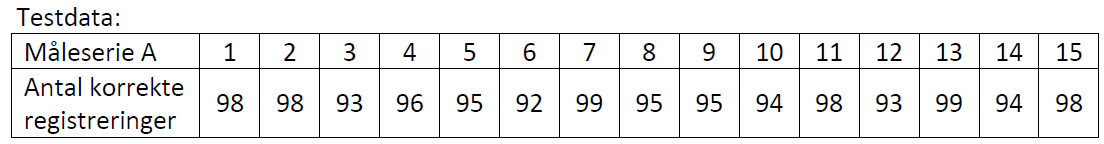

**a) Bestem fra testen den estimerede succesrate (sandsynligheden for korrekt registrering).**

AKR=[98 98 93 96 95 92 99 95 95 94 98 93 99 94 98];
trials=15*100

trials = 1500

succesiveTrials=sum(AKR)

succesiveTrials = 1437

sucessrate=succesiveTrials/trials

sucessrate = 0.9580

*Der er en sucessrate på 0.958*

**b) Hvilken test-statistik kan bruges til at teste om overvågningssystemet overholder kravet til korrekt registrering. Der skal gøre rede for, at betingelserne for den benyttede test-statistik er opfyldt, samt hvilken NULL-hypotese og alternative hypotese, der opstilles til testen.**

*Binomialfordelings test med normal approximation - da der er tale om succes og fejl scenarier.*

*Vi tester først betingelserne*


$$n\cdot p\Rightarrow 1500\cdot 0\ldotp 958=1437$$


trials*sucessrate

ans = 1437


$$n\left(1-p\right)\Rightarrow 1500\cdot \left(1-0\ldotp 958\right)=63\ldotp 00$$


trials*(1-0.958)

ans = 63.0000

I det at begge betingelser er over værdien 5 kan vi antage at der er approximatalt er tale om en normalfordeling med $\mu =0$ og $\sigma {\;}^2 =1$

Vi kan nu opstille en nullhypotese


$$\begin{array}{l}
H_0 :p{\;}_0 =0\ldotp 95,\;95%\;\textrm{af}\;\textrm{komponenterne}\;\textrm{registreres}\;\textrm{som}\;\textrm{forventet}\\
H_1 :p_0 \not= 0\ldotp 95,\;\;95%\;\textrm{af}\;\textrm{komponenterne}\;\textrm{registreres}\;\textrm{IKKE}\;\textrm{som}\;\textrm{forventet}
\end{array}$$


p0=0.95;

**c) Bestem p-værdien for de målte testdata. Opfylder overvågningssystemet kravet med et signifikans-niveau på 5%.**

Da dette er en binomial test kan vi se det som en normal distribution med $\mu =0$ og $\sigma {\;}^2 =1$


$$z=\frac{x-{\textrm{np}}_0 }{\sqrt{{\textrm{np}}_0 \left(1-p_0 \right)}}$$


z=(succesiveTrials-(trials*p0))/(sqrt((trials*p0)*(1-p0)))

z = 1.4216


$$p=2\cdot \left|1-\Phi \;\left(\left|z\right|\right)\right|$$


p=2*abs(1-normcdf(abs(z)))

p = 0.1551

*I det at vores p-værdi er på 0.1551, hvilket er over 0.05. kan vi ****IKKE**** forkaste vores nullhypotese*

**d) Bestem 95% konfidensintervallet for overvågningssystemet med de målte testdata.**


$$p_- =\frac{1}{n+1\ldotp {96}^2 }\left\lbrack x+\frac{1}{n+1\ldotp {96}^2 }-1\ldotp 96\sqrt{\frac{x\left(n-x\right)}{n}+\frac{1\ldotp {96}^2 }{4}}\right\rbrack$$



$$p_+ =\frac{1}{n+1\ldotp {96}^2 }\left\lbrack x+\frac{1}{n+1\ldotp {96}^2 }+1\ldotp 96\sqrt{\frac{x\left(n-x\right)}{n}+\frac{1\ldotp {96}^2 }{4}}\right\rbrack$$


Pmin=((1)/(trials+(1.96^2)))*(succesiveTrials+((1)/(trials+(1.96^2)))-1.96*sqrt(((succesiveTrials*(trials-succesiveTrials))/(trials))+((1.96^2)/(4))))

Pmin = 0.9453

Pmax=((1)/(trials+(1.96^2)))*(succesiveTrials+((1)/(trials+(1.96^2)))+1.96*sqrt(((succesiveTrials*(trials-succesiveTrials))/(trials))+((1.96^2)/(4))))

Pmax = 0.9658

*Konfidensintervallet ligger mellem [0.9453;0.9658]*

*Da 0.95 indegår i konfidens intervalet kan vi ikke afvise vores nullhypotese*

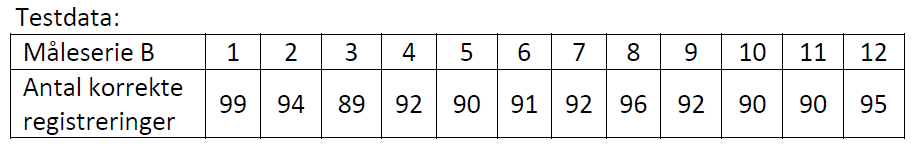

**e) Hvilken test skal laves for at undersøge om de to datasæt er forskellige?**

*Uparret t-test Fordi vi har 2 test sæt som ikke er ens og har en ukendt varians.*

**f) Opstil NULL-hypotese, beregn p-værdien og konkluder om de to datasæt er ens med 5% signifikansniveau.**


$$\begin{array}{l}
H_0 :\delta_0 =0\;,\;\textrm{datas\aettene}\;\textrm{er}\;\textrm{ens}\\
H_1 :\delta_0 \not= 0\;,\;\textrm{datas\aettene}\;\textrm{er}\;\textrm{IKKE}\;\;\textrm{ens}
\end{array}$$


AKRB=[99 94 89 92 90 91 92 96 92 90 90 95];
trialsB=12*100

trialsB = 1200

succesiveTrialsB=sum(AKRB)

succesiveTrialsB = 1110

succesRateB=succesiveTrialsB/trialsB

succesRateB = 0.9250

korrektMaalingPr100A=succesiveTrials/length(AKR)

korrektMaalingPr100A = 95.8000

korrektMaalingPr100B=succesiveTrialsB/length(AKRB)

korrektMaalingPr100B = 92.5000

d=korrektMaalingPr100A-korrektMaalingPr100B

d = 3.3000

SampleVarianceA=var(AKR)

SampleVarianceA = 5.6000

SampleVarianceB=var(AKRB)

SampleVarianceB = 8.8182

pooledVar=(1/((length(AKR)-1)+(length(AKRB)-1)))*((length(AKR)-1)*SampleVarianceA+(length(AKRB)-1)*SampleVarianceB) 

pooledVar = 7.0160


$$t=\frac{d}{\sqrt{\textrm{pooledvar}}\cdot \sqrt{\frac{1}{\textrm{length}\left(\textrm{AKR}\right)}+\frac{1}{\textrm{length}\left(\textrm{AKRB}\right)}}}$$


t=d/((sqrt(pooledVar))*(sqrt((1/length(AKR))+(1/length(AKR)))))

t = 3.4119


$$\textrm{pval}=2\cdot \;\left(1-t_{\textrm{cdf}} \left(\left|t\right|,n-1\right)\right)$$


p=2*(1-tcdf(abs(t),length(AKR)+length(AKRB)-2))

p = 0.0022

*Da pværdien er under 0.05 kan vi forkaste hypotesen om at datasættene er ens, hvilket betyder at de 2 systemer virker forskelligt*